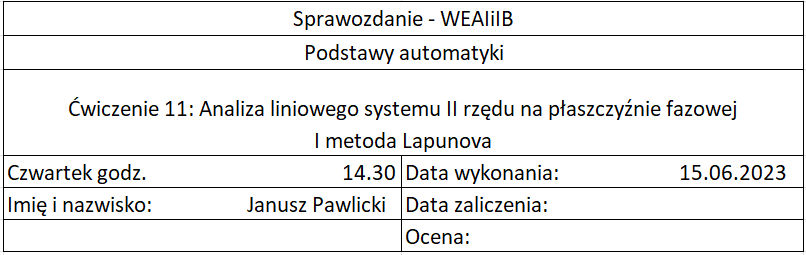

## 1. Wstęp teoretyczny:

W pierwszej metodzie Lapunowa analizuje się pochodną funkcji Lapunowa wzdłuż trajektorii systemu dynamicznego.

Jeśli pochodna jest ujemna lub zerowa na całym obszarze analizy, to oznacza, że system jest stabilny.

Jeżeli pochodna jest dodatnia na pewnym obszarze, to wskazuje na niestabilność systemu.

Jednak pierwsza metoda Lapunowa nie daje informacji na temat stabilności granicznej ani innych właściwości dynamicznych systemu.

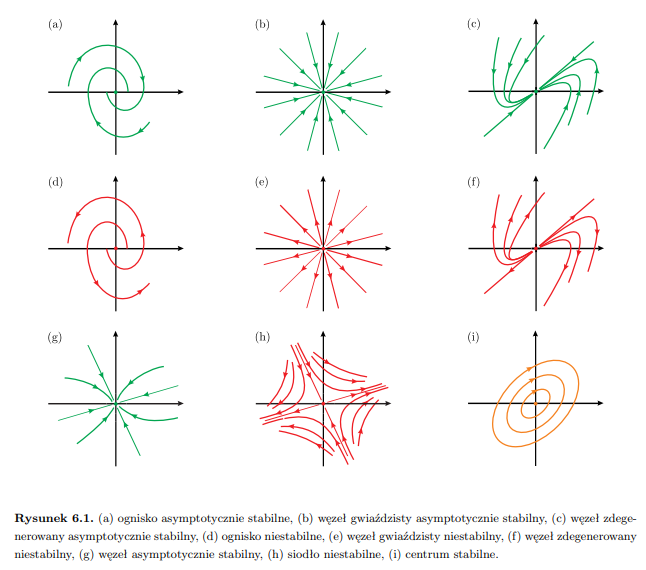

## 2. Przebieg laboratorium

Będziemy analizować stabilność nieliniowego systemu dynamicznego opisanego jednorodnym, nieliniowym równaniem różniczkowym 2 rzędu:

 

Równanie to opisuje np. ruch ciężarka na sprężynie, gdzie x(t) to położenie ciężarka, współczynnik b opisuje rozpraszanie energii w układzie, współczynniki c oraz d opisują nieliniową sprężynę (d<0 sprężyna miękka, d>0 sprężyna twarda). W przypadku gdy współczynnik d =0 otrzymujemy znany z poprzedniego ćwiczenia układ liniowy. Jeżeli założymy, że zmiennymi stanu w tym układzie są: położenie ciężarka x(t) oraz prędkość jego ruchu v(t), to równanie (1) może być zapisane w postaci równania stanu: 

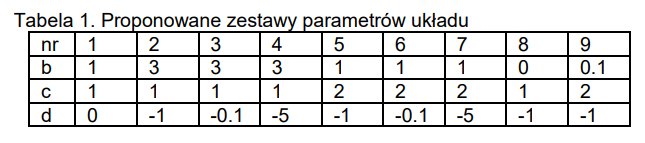

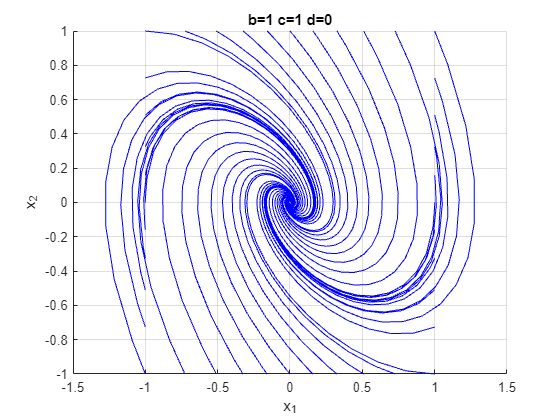

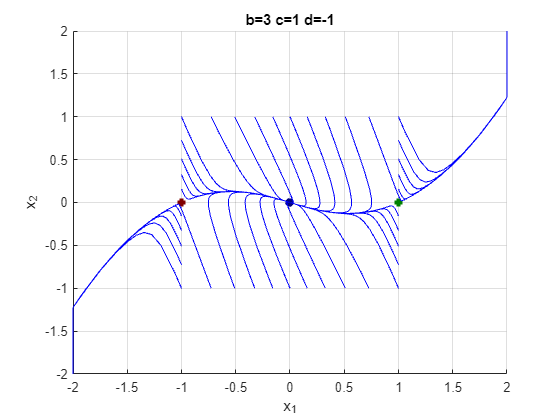

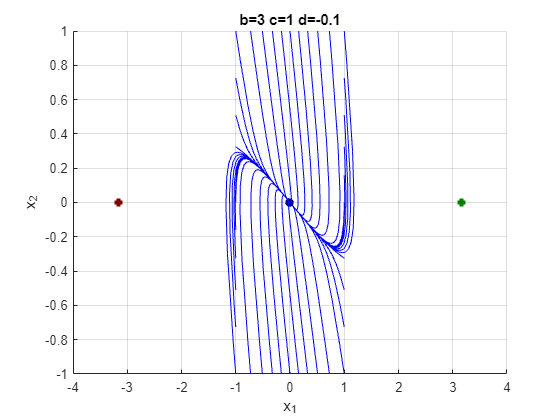

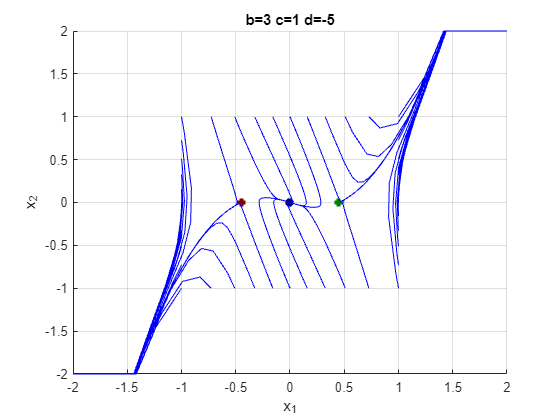

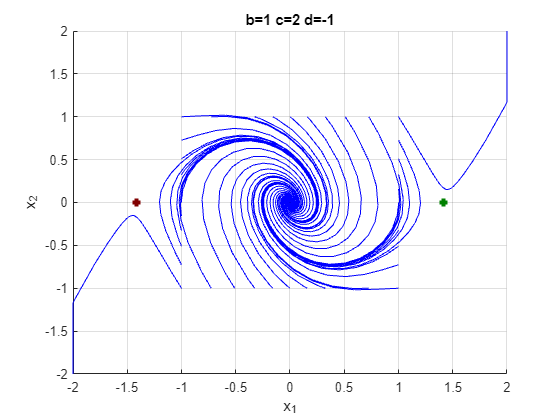

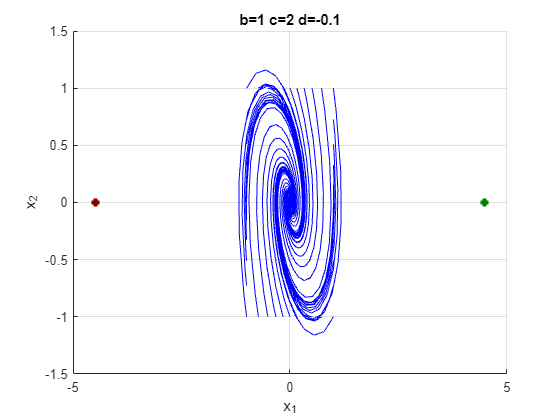

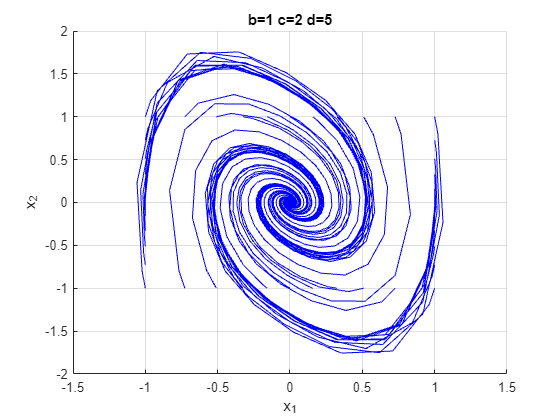

B=[1,3,3,3,1,1,1,0,0.1]; % wiersz tabeli
C=[1,1,1,1,2,2,2,1,2]; % wiersz tabeli
D=[0,-1,-0.1,-5,-1,-0.1,5,-1,-1]; % wiersz tabeli
for i=1:9
    b=B(i);
    c=C(i);
    d=D(i);
    T=10;
    P=20;
    figure;hold on; grid on;
    if d<0
        plot(sqrt(-c/d),0,"+",'linewidth',3,'color',[0 0.5 0]) %\
        plot(-sqrt(-c/d),0,"+",'linewidth',3,'color',[0.5 0 0]);%| = Punkty niestabilne
        plot(0,0,'*','linewidth',3,'color',[0 0 0.5]);         %| = Punkt stabilny
    end
    a=0:(pi/P):(2*pi);
    X1=[cos(a);sin(a)];
    X2=X1./[max(abs(X1));max(abs(X1))];
    M=size(X2,2);
    for m=1:M
        x0=X2(:,m);
        clear sim % nie wyczyszczenie parametru sim powodowało błąd ze względu na nadpisywanie pamięci
        sim=sim('uklad',T);
        plot(sim.x2,sim.x1,'b-');
        title(strcat('b=',num2str(b),' c=',num2str(c),' d=', num2str(d)))
        xlabel('x_1');ylabel('x_2');
    end
end

## 3. Wnioski:

Wykonanie ćwiczenia pomogło z w zrozumieniu płaszczyzn fazowych. Poznałem również metodę Lapunova.

Dzięki wykonaniu tego ćwiczenia odświeżyliśmy sobie metodę Lapunowa i jak badać stabilność na podstawie płaszczyzn fazowych.

Analiza portretów fazowych wykazała, że:

- Układ 1 był układem liniowym.

- Układy od 2 do 7 był stabilne asymptotycznie.

- Układy 8 i 9 były niestabilne asymptotycznie.

Dla układu stabilnego aperiodycznie linie wykresu zmierzają do środka układu, co oznacza, że obiekty wytrącone z równowagi wracają do niej. 

Przebieg układu oscylacyjnego nietłumionego oscyluje wokół punktu równowagi, jednak nie zmierza do niego. 

Układy niestabilne po wytrąceniu z punktu równowagi nie wracają do niego.